# Visualization of graph data

## Small graph data

addpath("functions")
set(0,'DefaultFigureWindowStyle','docked')

[nodes,edges,n,emb,M,P,Cos,Sin] = build("small");


merging...
Elapsed time is 0.458417 seconds.

building M...
Elapsed time is 0.002319 seconds.

building P...
Elapsed time is 0.002073 seconds.


% load materials\small.mat

### Visualization

The sparsity patterns for the Sin and Cos matrices.

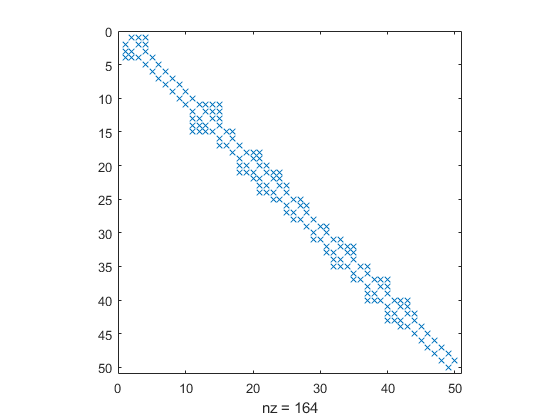

spy(Cos,'x');

The head of the M matrix. Its pattern should be falling diagonals with verticals at each iteration.

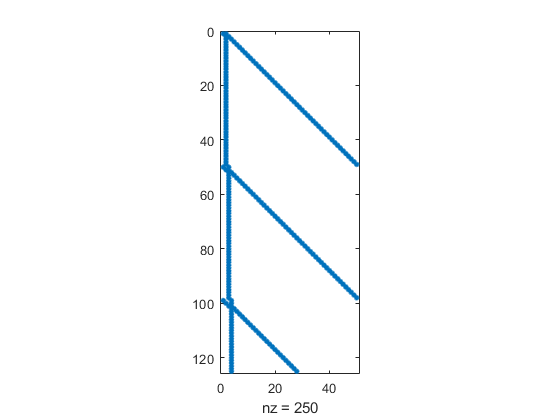

spy(headN(M,ceil(2.5*n)));

Before we go on plotting, we created a function *(see addpoints)* to plot some points over a color gradient to keep track of the location of some specific points. Through this we get a better grasp of the embeddings' changes. *(See *[https://de.mathworks.com/help/matlab/ref/uisetcolor.html](https://de.mathworks.com/help/matlab/ref/uisetcolor.html)*)*

% uisetcolor for the colors
col1 = [1, 0, 0];
col2 = [0, 1, 0];

Plot now the actual graph that is given. **Cos** does function as the adjacency matrix here. For the real adjacency matrix get the nonzeros from Cos. If no adjacency is given we can take only the vertices without interconnections. *(See section ****large graph****)*

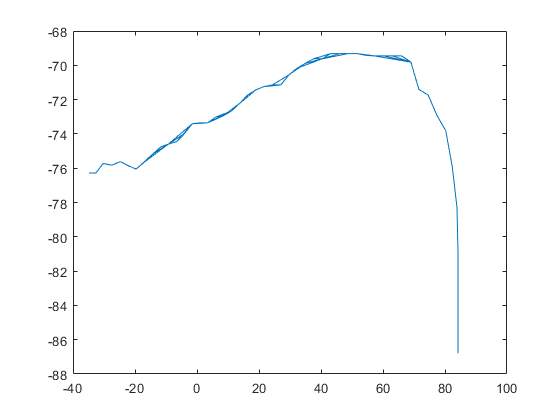

gplot(Cos,nodes(:,2:3))

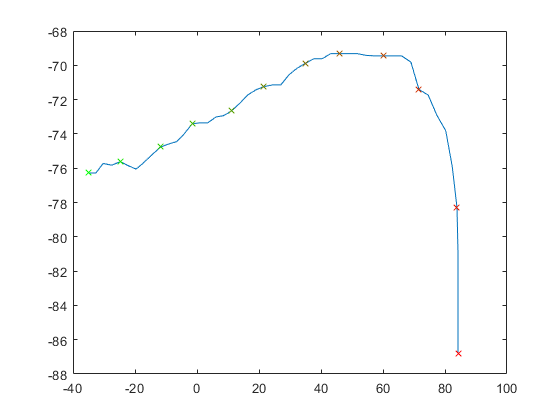

% the following two lines were rendered unnecessary due to
% plotColorgradient()
% plot(nodes(:,2),nodes(:,3),".")
% addpoints(n/4,col1,col2,nodes(:,2:3))
plotColorgradient(n/4,col1,col2,nodes(:,2:3),true,true)

Display the first embedding solution. This embedding was calculated by improper usage of **inv()**.

Update 21-01-04: emb1 no longer available

% gplot(Cos,emb1)
% plotColorgradient(n/4,col1,col2,emb1,true,true)

Display the embedding solution. This embedding was calculated by the proper way of **A\b**. Here **b** was a matrix as well. *(See ****building.mlx****)*

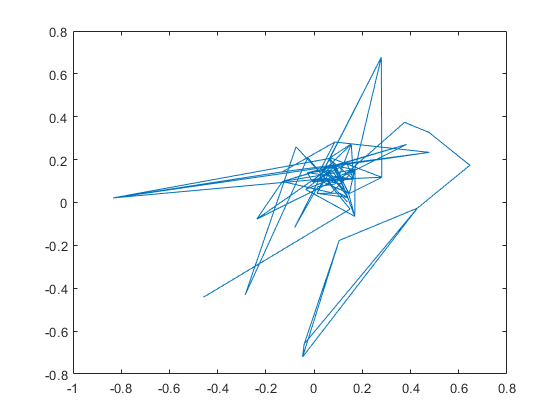

gplot(Cos,emb)

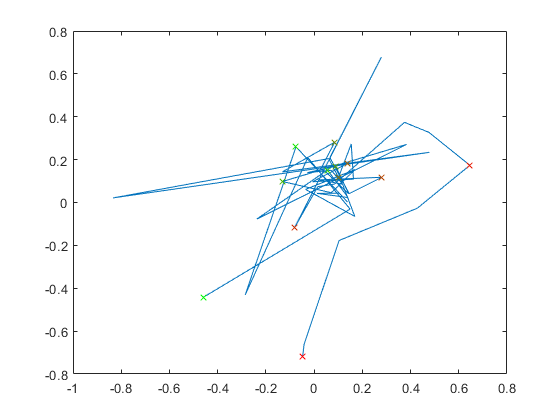

% plot(emb(:,1),emb2(:,2),".")
plotColorgradient(n/4,col1,col2,emb,true,true)

On this last graph there is visible some circular structure. This is interesting in a way that it differs the first version of the improper usage of **inv()** a lot. This might be interesting for understanding the desired solution of embeddings and worth discussing more.

### Clustering

Let us try **clustering **with **dbscan() **and **kmeans()**.

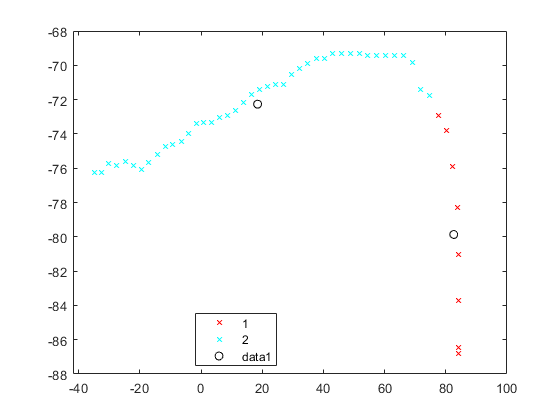

plotCluster(nodes,6,5,'on',false,"db");

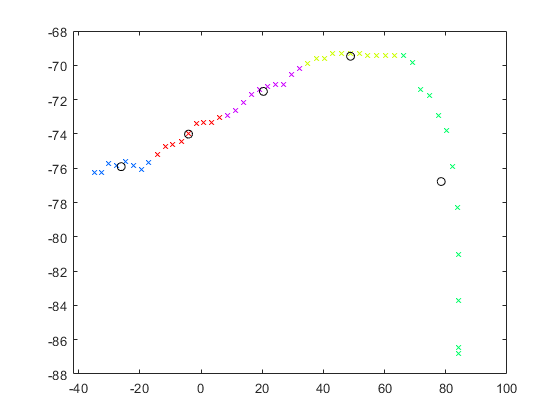

plotCluster(nodes,1.2,5,'off',false,"km");

### Aftermath

clc
clear

## Large graph data

Here we want to use the **large data set** Tristan gave us instead of the partial one above. Due to the large number of nodes and edges we cannot calculate an adjacency matrix. This would break the limit of data storage as it demands **9.4GB**. As for now we just display the nodes without interconnecting edges.

[nodes,edges,n,emb,M,P,Cos,Sin] = build("large");

Elapsed time is 124.096777 seconds.

building M...
Elapsed time is 0.172697 seconds.

building P...
Elapsed time is 0.048735 seconds.


% load materials\large.mat

### Visualization

The sparsity patterns for the Sin and Cos matrices.

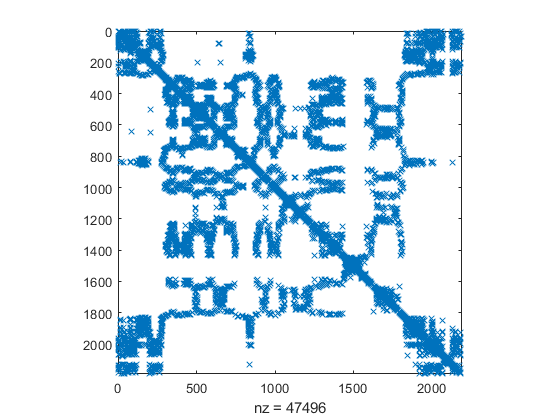

spy(Cos,'x');

The head of the M matrix. Its pattern should be falling diagonals with verticals at each iteration.

% spy(headN(M,ceil(2.5*n)));

Plot here the actual graph that is given. **Cos** does function as the adjacency matrix here. For the real adjacency matrix get the nonzeros from Cos. If no adjacency is given we can take only the vertices without interconnections. *(See section ****large graph****)*

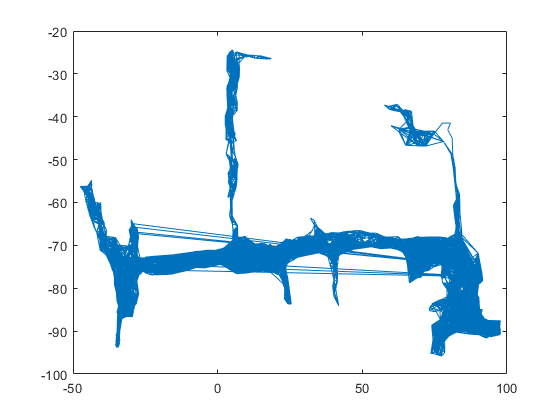

% uisetcolor for the colors
col1 = [1, 0, 0];
col2 = [0, 1, 0];

gplot(Cos,nodes(:,2:3))

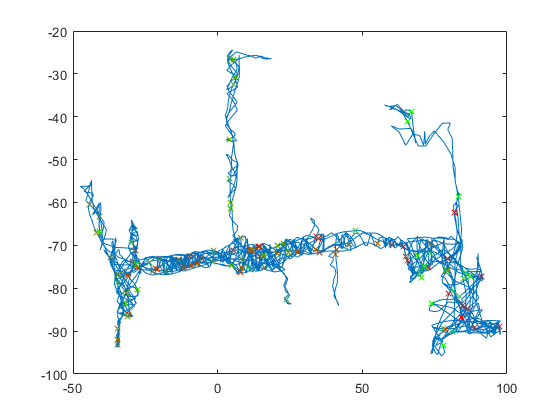

% plot(nodes(:,2),nodes(:,3),".")
plotColorgradient(n/20,col1,col2,nodes(:,2:3),true,true)

Display the first embedding solution. This embedding was calculated by improper usage of **inv()**.

Update 21-01-04: emb1 no longer available

% gplot(Cos,emb1)
% % plot(emb1(:,1),emb1(:,2),".")
% plotColorgradient(2,col1,col2,emb1,true,true)

Display the second embedding solution. This embedding was calculated by the proper way of **A\b**. Here **b** was a matrix as well. *(See ****building.mlx****)*

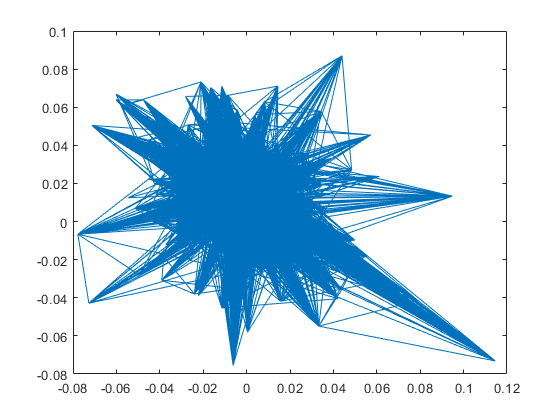

gplot(Cos,emb)

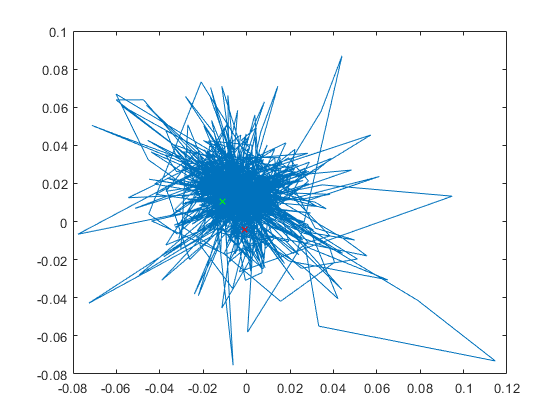

% plot(emb2(:,1),emb(:,2),".")
plotColorgradient(2,col1,col2,emb,true,true)

On this last graph there is visible some circular structure. This is interesting in a way that it differs the first version of the improper usage of **inv()** a lot. This might be interesting for understanding the desired solution of embeddings and worth discussing more.

### Clustering

Let's again cluster, this time the large graph. It is a bit more interesting than the small graph.

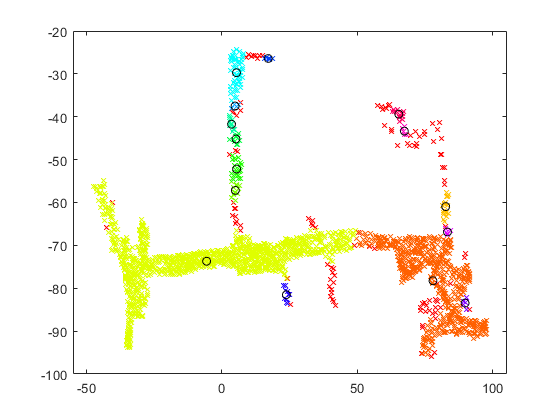

plotCluster(nodes,1.5,5,'off',false,"db");

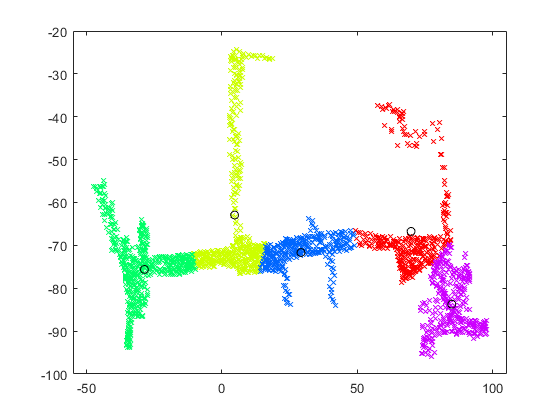

plotCluster(nodes,1.2,5,'off',false,"km");

### Aftermath

clc
clear

## Tests

### 01

addpath("functions")

[nodes,edges,n,emb,M,P,Cos,Sin] = build("01");


merging...
Elapsed time is 0.013378 seconds.

building M...
Elapsed time is 0.000078 seconds.

building P...
Elapsed time is 0.000060 seconds.



% col1 = [0, 1, 0];
% col2 = [1, 0, 0];
% 
% spy(Cos,'x');
% spy(M)

why is the embedding not calculated as desired?

% gplot(Cos,emb)
% plot(emb(:,1),emb(:,2),".")
% plotColorgradient(2,col1,col2,emb,true,true)

### Aftermath

clc
clear

### TODO

Consider making the directed graph an undirected on from Tristans data. For this we need to check first whether the two edge angles are opposite to each other...

If they are **not, **then we cannot do this! 

If they **are,** then we can savely generate an undirected graph from the data

**EDIT**

The in and out angles should not be the same, as we precisely for this occasion to want to minimize the angular error. The shift of angles over the graph (north direction) should affect the two respective directed edges between two nodes in such way, that the angles do not match...

Check again on this statement!

For visualization: We add up the north shifts of each node to the angles of the outgoing edges of the respective nodes, so we get it drawing accordingly in the graphs! With sufficient north shifts we should be able to see, that the edges do not hit target (the ingoing nodes), as they do in a graph without north shifts...

For this we need to draw not a gplot() graph, as the lines are not drawn according to the angles there:

**EDIT 20210202**

The embeddings either do not get drawn/calculated, as the given graphs and their respective matrices are singular, or the nodes do get embedded in the same spatial position in the graph (see plotCompare("03")) and are not distiguishable, while fulfilling the desired goal of minimizing differences.

### drawing function

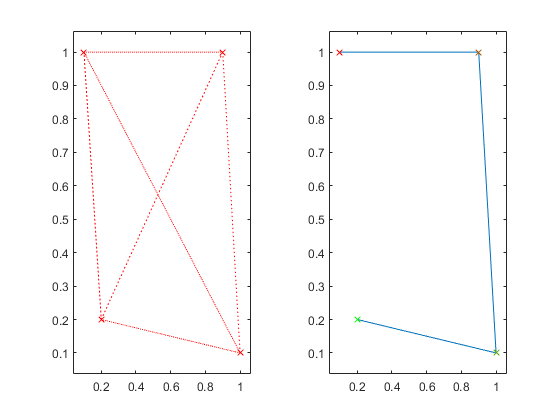

plotTiled("01");

plotTiled("01b");

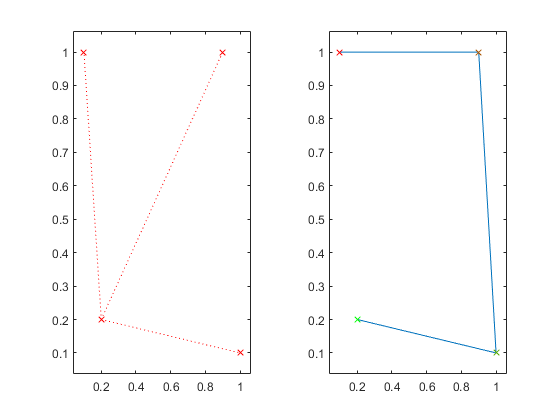

plotTiled("02");

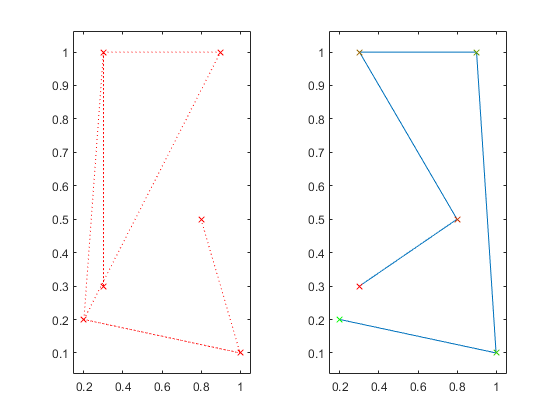

plotTiled("03");

### draw angled lines

Here we try to draw the nodes and the lines from the nodes to the points, but not from point to point, but from the node at an angle with the fitting length, e.g. the length between the two nodes.

If we choose to reread the data (attribute in **plotCompare()**), we get a warning when the matrix in the embedding calculation is singular. For an example call **build("01")**.

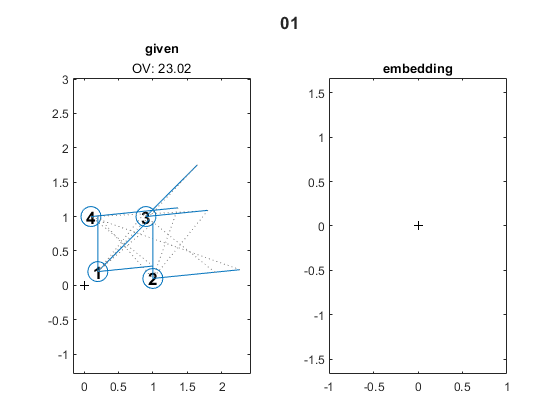

plotCompare("01",0,0);

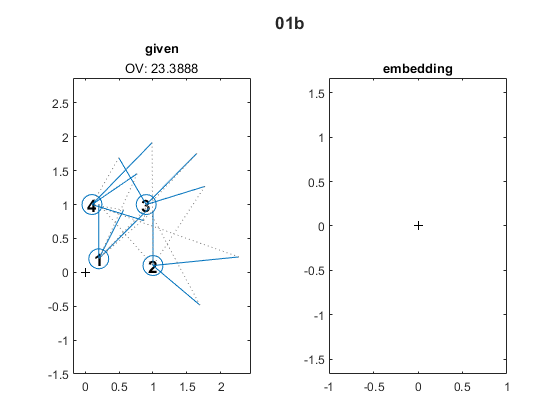

plotCompare("01b",0,0);

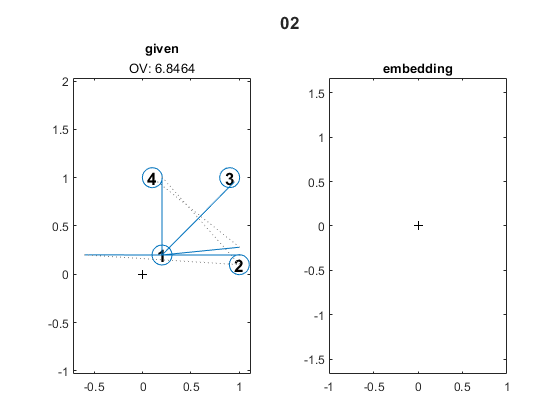

plotCompare("02",0,0);

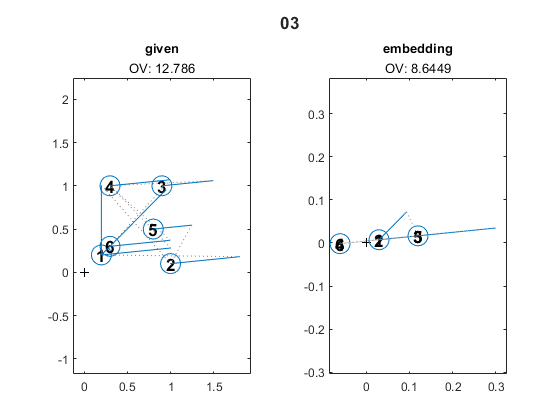

plotCompare("03",0,0);

This last plot does show what is to be done:

The embedding should result in an arc, as the edges do not form any form of cycles but rather a single path from node **1 **to node **6**. The arc embedding would minimize the differences between the angles.

**TODO**

plotCompare("04",0,0);

While the embedding of **04b** does form a line, nodes **03** is farthest to the right, while nodes **04** to **06 **seem to inhabit the same positions as at least one other node...

Why does the emedding not form a straight line?

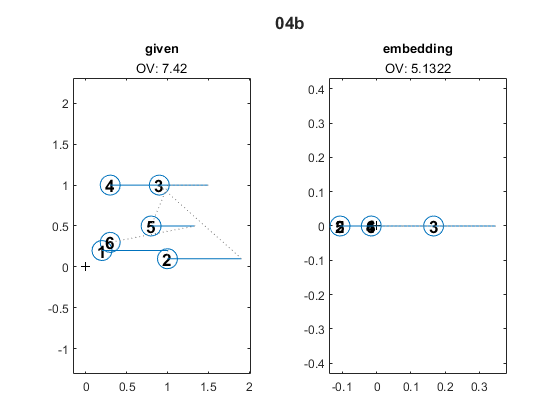

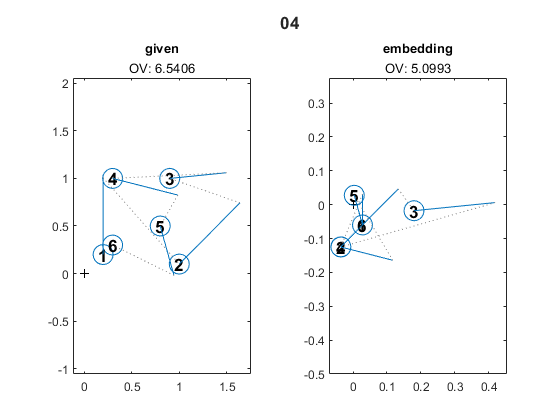

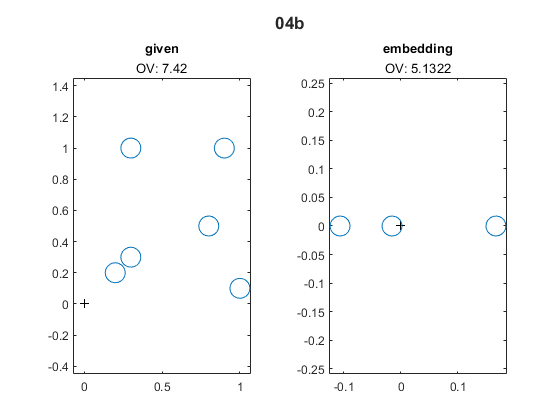

drawOV = 1

plotCompare("04b",0,0);
plotCompareOptions("04b",0,1,1,0,0,0,0,0,0,0);

With **04c** we generated an initial nearly perfect embedding with a very low OV. Clearly the supposed to be best embedding got a much higher rating on the OV and does not fulfill the desired conditions.

Investigation on this matter will be continued.

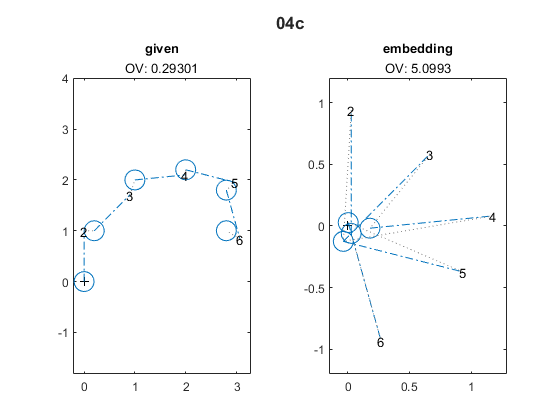

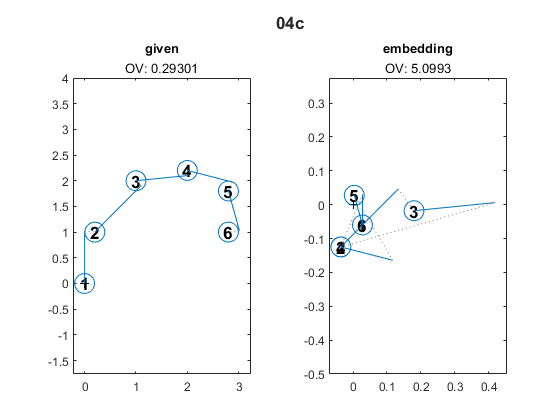

drawOV = 1

plotCompare("04c",0,0);
plotCompareOptions("04c",0,1,1,0,0,1,1,1,1,1);

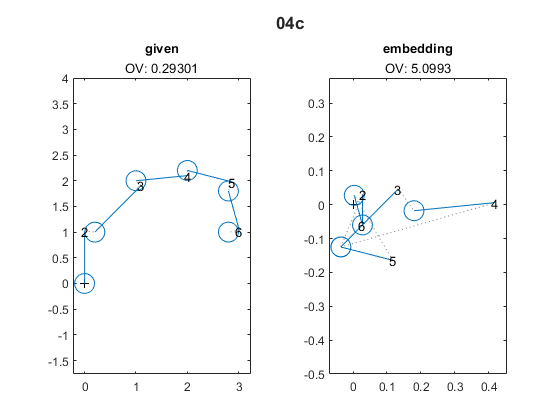

drawOV = 1

plotCompareOptions("04c",0,1,1,0,0,1,0,1,1,1);